chan=1;
nsPerPoint=spc.datainfo.psPerUnit/1000

nsPerPoint = 0.0489

range = round([spc.fits{chan}.fitstart spc.fits{chan}.fitend]/nsPerPoint)

range =      1   256


x_project = 1:length(range(1):range(2))

x_project =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x_project2 = repmat(x_project, [1,spc.SPCdata.scan_size_x*spc.SPCdata.scan_size_y])

x_project2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x_project3 = reshape(x_project2, length(x_project), spc.SPCdata.scan_size_y, spc.SPCdata.scan_size_x)

x_project3 = x_project3(:,:,1) =

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     

sumX_project = spc.imageMods{chan}(range(1):range(2),:,:).*x_project3

sumX_project = sumX_project(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

sumX_project1 = sum(sumX_project, 1)

sumX_project1 = sumX_project1(:,:,1) =

         152          99         101         125         467        1671        1481        1880        2122        1401        2766        4027        4580        8496       24051       48174       46683       28567        8798        7481        5679        2855        2041        1469         909         671         630         252         587          78         355         667         313         386         221         218         221          66           0         212         251         333         441          92         117         301         525         216         598         147         490         397         362         197         554         280        1115        1742        2818        5542        4979        5164        5497        3305        6155        5705        4547        3653        3684        2940        1278        2213        1745        1529        2327        2916        2207        3617        2378        3160


% range: 20:246 227 channels
% x_project: 1:1:227
% x_project2: 1x3719168 227*128*128=3719168
% x_project3: 227*128*128
% spc.imageMods{chan}(range(1):range(2),:,:) 227*128*128
% sumX_project: 227x128x128
% sumX_project1: 1*128*128

sum_project = sum(spc.imageMods{chan}(range(1):range(2),:,:), 1);
sum_project1 = reshape(sum_project, spc.SPCdata.scan_size_y, spc.SPCdata.scan_size_x); 
bw = (sum_project1 > 0)

bw = 128×128 logical array
   1   0   1   1   0   1   1   1   1   1   1   1   0   0   0   1   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   0   0   1   1   0   1   0   0   1   0
   1   1   1   1   1   0   1   1   1   1   0   0   1   1   0   1   1   0   0   0   0   1   1   0   0   0   0   0   1   0   1   0   0   0   0   1   1   1   0   1   0   1   0   0   1   1   1   0   0   1
   1   1   1   1   0   1   1   1   0   1   1   1   1   1   1   1   0   1   0   1   0   1   1   1   0   0   0   0   0   0   0   1   1   1   1   0   0   0   1   0   1   0   0   0   0   0   1   0   0   0
   1   1   1   0   1   1   1   1   1   1   1   0   1   1   0   1   1   1   1   1   1   1   0   0   1   0   0   0   0   1   1   1   0   0   0   0   0   1   0   1   0   0   1   0   0   0   1   0   1   0
   1   1   1   1   1   1   1   1   1   1   1   0   1   1   1   0   0   0   1   0   1   0   1   0   0   0   0   1   1   1   0   0   0   0   0   0   0   1   0   0   0   0 


% sum_project: 1*128*128
% sum_project1: 128*128
% bw: 128*128

pos_max2=0;
spc.lifetimeMaps{chan}(bw) = (sumX_project1(bw)./sum_project1(bw))*nsPerPoint-pos_max2;

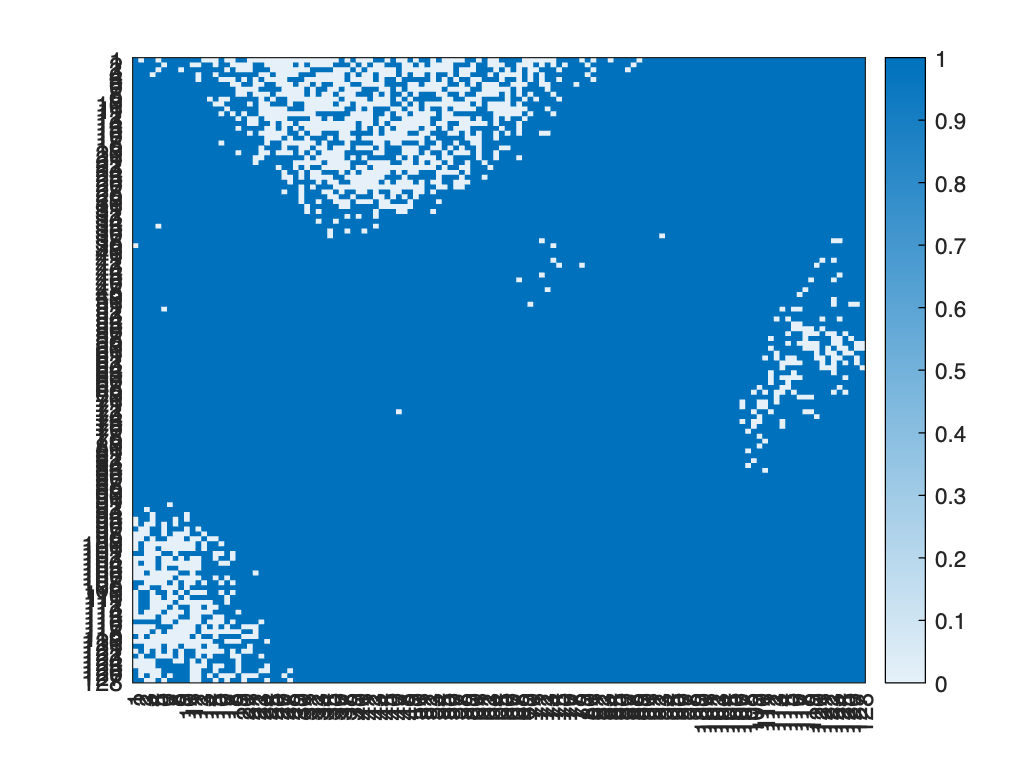

bw1=double(bw);
figure
heatmap(bw1)
grid off

fc=1;
mask=gui.gy.rois{1}.mask;
mask1=double(mask);
nTimesTau=mask .* spc.projects{fc} .* spc.lifetimeMaps{fc};
val=sum(nTimesTau(:)) / sum(spc.projects{fc}(:) .* mask(:))

val = 5.1556

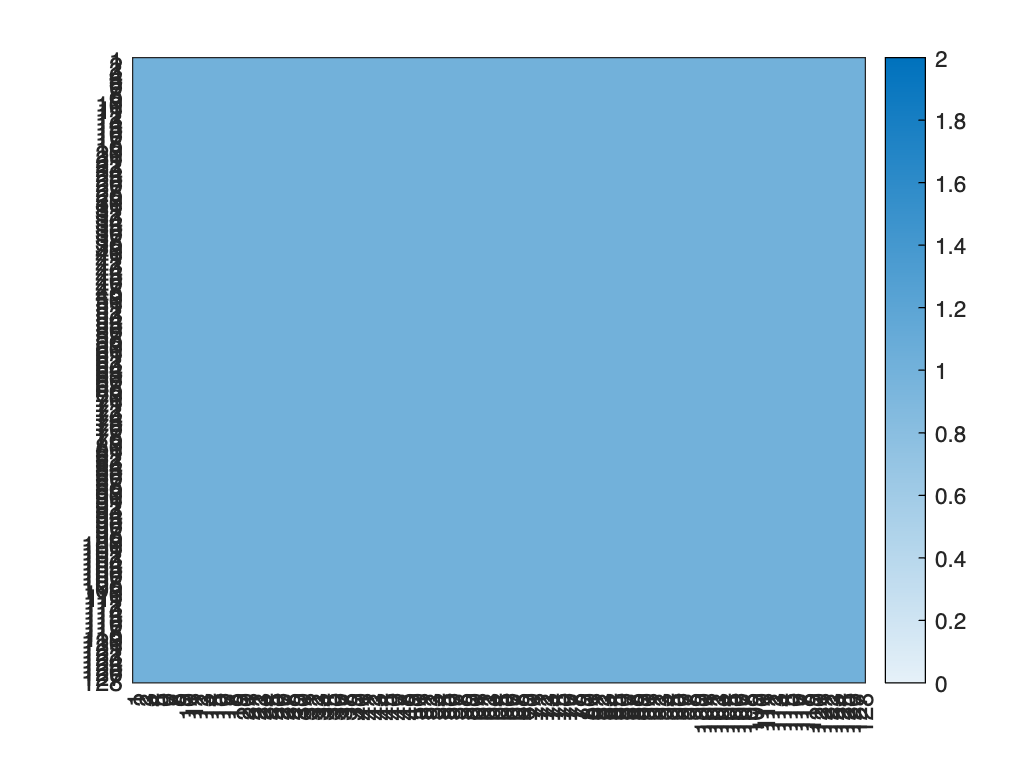

figure
heatmap(mask1)
grid off

lifetimes_total=zeros(1,256);
projects=zeros(128,128);
for i=1:128
    for j=1:128
        lifetimes_total=lifetimes_total+spc.imageMods{1}(:,i,j)';
        projects(i,j)=sum(spc.imageMods{1}(range(1):range(2),i,j));
    end
end
